Theshold calculator

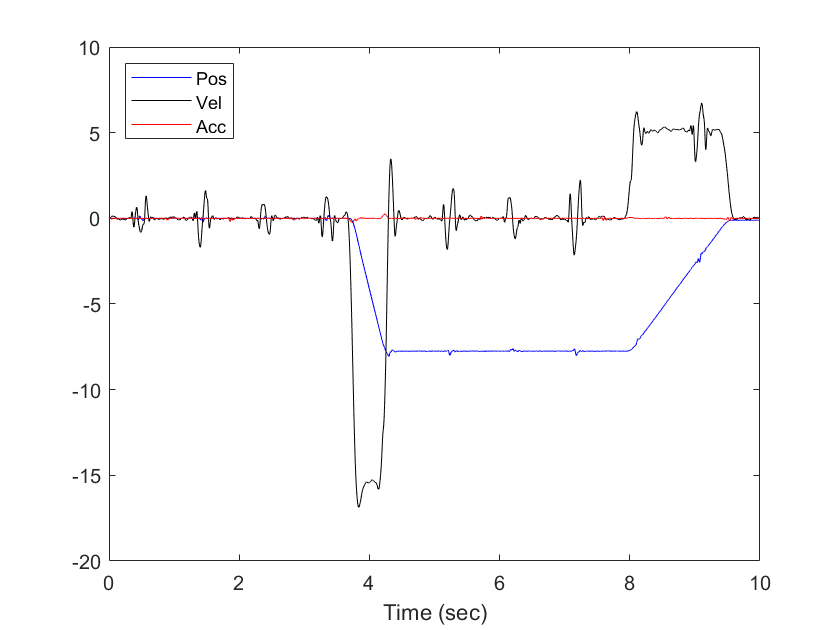

load("Trial05.mat")
T= atime;
Pos = data.analog.platemotion(:,2);
Vel = data.analog.platemotion(:,4);
Acc = data.analog.platemotion(:,6);
clf
plot(T,Pos,'b')
hold on
plot(T,Vel,'k')
plot(T,Acc, 'r')
legend({'Pos', 'Vel', 'Acc'}, 'Location','northwest')
xlabel('Time (sec)')

Tsmall = T(1:550);
Psmall = Pos(1:550);
Vsmall = Vel(1:550);
Asmall = Acc(1:550);

figure 
plot(Tsmall,Psmall,'b')
hold on
plot(Tsmall,Vsmall,'k')
plot(Tsmall,Asmall, 'r')
Pstd = std(Psmall);
Vstd = std(Vsmall);
Astd = std(Asmall);

Pmin = mean(Psmall) - 4*Pstd;
Pmax = mean(Psmall) + 4*Pstd;
Vmin = mean(Vsmall) - 4*Vstd;
Vmax = mean(Vsmall) + 4*Pstd;
Amin = mean(Asmall) - 4*Astd;
Amax = mean(Asmall) + 4*Astd;

Pthres1 = find(Pos <= Pmin);
Pthres2 = find(Pos >= Pmax);
Pthres = [Pthres1; Pthres2];
Pthres = min(Pthres);

Vthres1 = find(Vel <= Vmin);
Vthres2 = find(Vel >= Vmax);
Vthres = [Vthres1; Vthres2];
Vthres = min(Vthres);

Athres1 = find(Acc <= Amin);
Athres2 = find(Acc >= Amax);
Athres = [Athres1; Athres2];
Athres = min(Athres);

figure
plot(T,Pos,'b')
hold on
plot(T,Vel,'k')
plot(T,Acc, 'r')
xline(T(Pthres),'b')
xline(T(Vthres), 'k')
xline(T(Athres), 'r')

figure
plot(T,Pos,'b')
hold on
plot(T,Vel,'k')
plot(T,Acc, 'r')
ind = platStart (Acc);
xline(T(ind))

This section is dedicated to identifying the frequency of the bursts seen in the kinematics (particually position and acceleratin) 

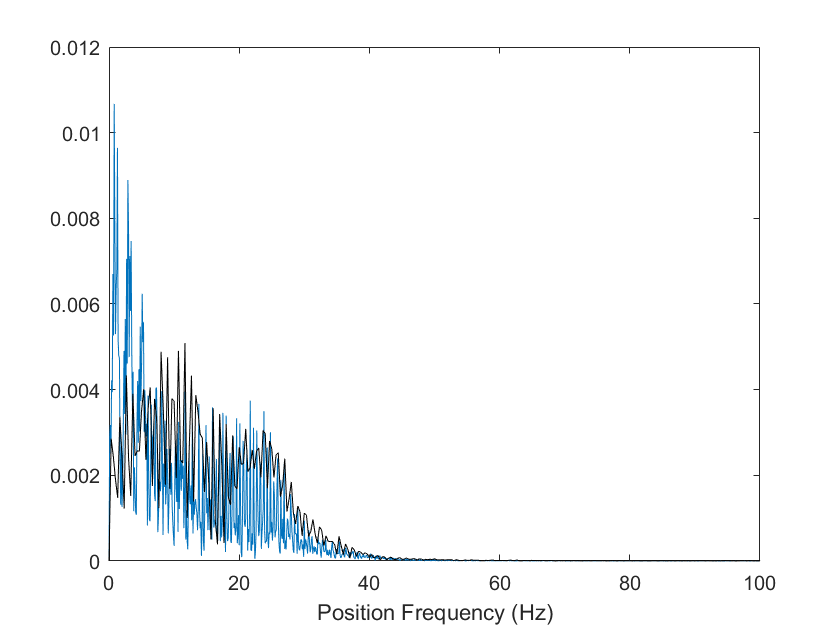

clf    
Fs = data.analog.samplerate; %Sampling Frequency
T = 1/Fs;
X = Acc; %Signal
L = length(X); %Signal length
X = X - mean(X);
Y = fft(X);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1);
xlim([0 100])
xlabel("Position Frequency (Hz)")


Fs = data.analog.samplerate; %Sampling Frequency
T = 1/Fs;
X = Acc(1:3000); %Signal
L = length(X); %Signal length
X = X - mean(X);
Y = fft(X);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
hold on
plot(f,P1,'k');
xlim([0 100])
xlabel("Position Frequency (Hz)")

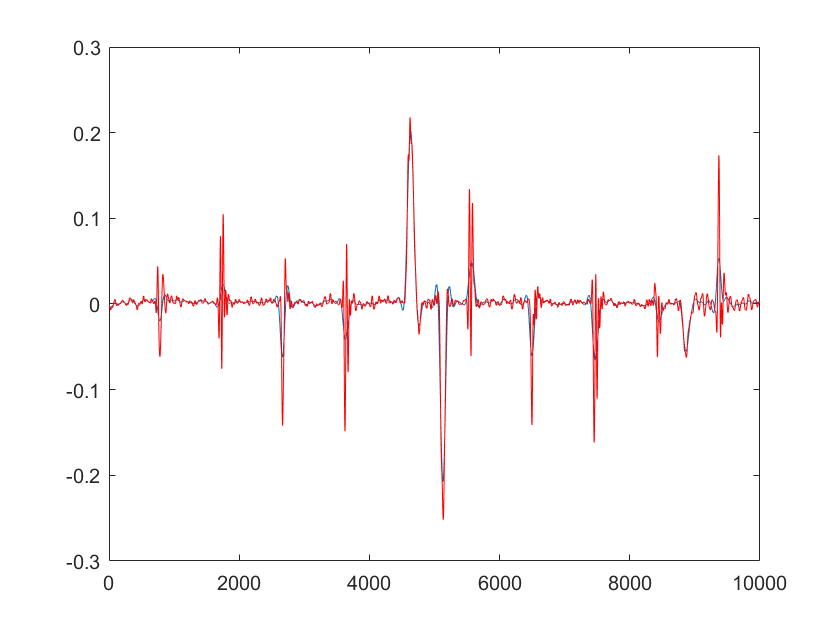

%Creating filter
%butter
N = 4; %order of the filter
Wn = 8/500; %cutoff over half of sampling rate
[B,A] = butter(N,Wn,'low');
AccFilter = filtfilt(B,A,Acc);

clf
plot(AccFilter)
hold on
plot(Acc, 'r')